# Useful functions in polar coodinates

## polarplot, plot line in polar coordinates

### plot a circle

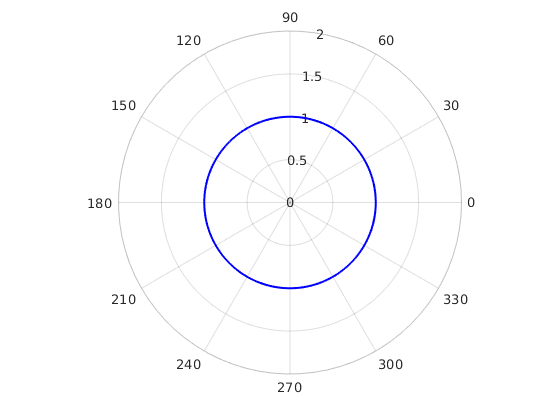

theta = 0: pi/100: 2*pi;
rho = 1*ones(length(theta));
figure
polarplot(theta,rho,'-','linew',1.5,'color','b');

### plot a sine wave

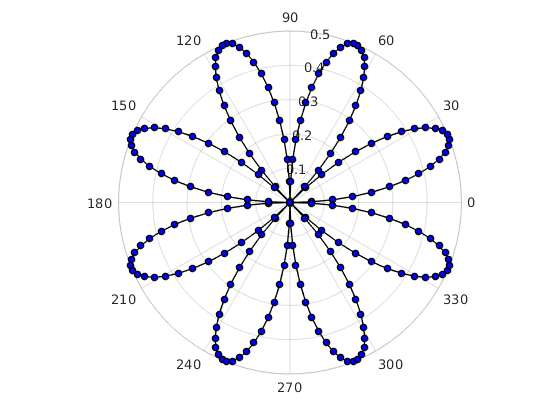

theta = 0: pi/100: 2*pi;
rho = sin(2*theta).*cos(2*theta);
figure
polarplot(theta,rho,'o-','linew',1,'color','k','markers',5,'markerf','b');

### plot a complex

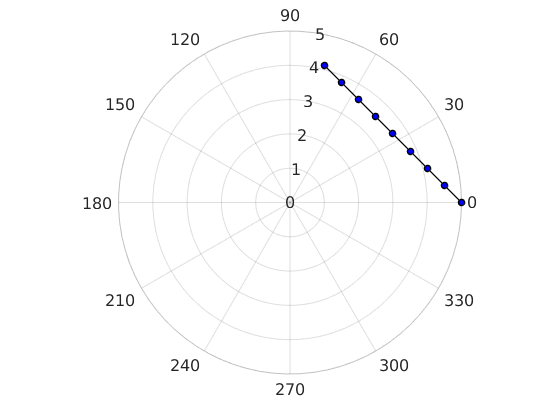

x = 1: 0.5: 5;
y = 4: -0.5: 0;
z = x+1i*y;
figure
polarplot(z,'o-','linew',1,'color','k','markers',5,'markerf','b');
ax = gca;
ax.FontSize=12;

## polarscatter, scatter chart in polar coordinates

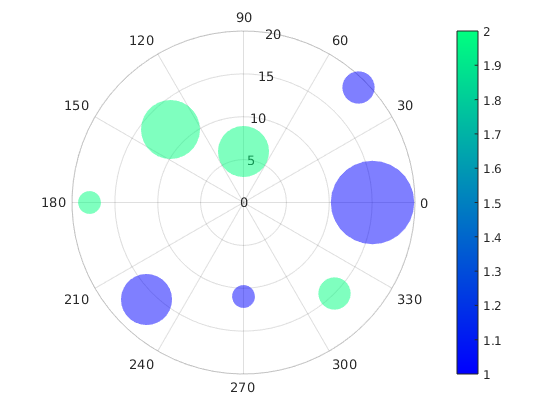

th = pi/4:pi/4:2*pi;
r = [19 6 12 18 16 11 15 15];
sz = 100*[6 15 20 3 15 3 6 40];
c = [1 2 2 2 1 1 2 1];
polarscatter(th,r,sz,c,'filled','MarkerFaceA',.5);
colormap("winter")
colorbar

# Rose diagram

## Polarhistogram to plot histogram chart in polar coordinates

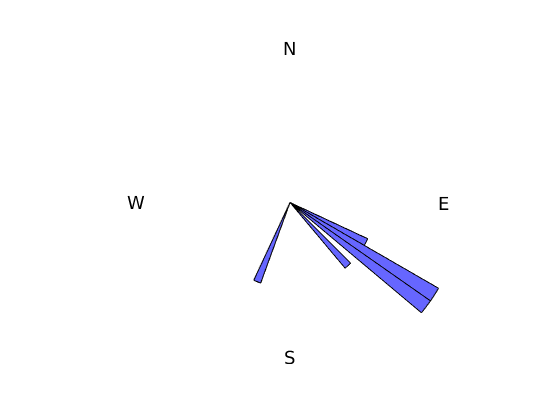

theta = [115 125 125 120 200 120 135];
theta = deg2rad(theta);
polarhistogram(theta,'binw',pi/36,'normalization','count','facec','b') %
ax = gca;
% ax.RTickLabelRotation = 45;
% ax.ThetaMinorTick = 'on';
% ax.TickLength = [0.02 0];
ax.ThetaZeroLocation = 'top';
ax.ThetaDir = 'clockwise';
% ax.FontSize = 12;
% ax.RTick = 0:1:3;
% ax.LineWidth = 1.5;
% ax.Box = 'off';
text(0,1.8,'N','HorizontalAlignment',"center",'FontSize',14);
text(deg2rad(90),1.8,'E','HorizontalAlignment',"center",'FontSize',14);
text(deg2rad(180),1.8,'S','HorizontalAlignment',"center",'FontSize',14);
text(deg2rad(270),1.8,'W','HorizontalAlignment',"center",'FontSize',14);
% ax.ThetaGrid = 'off';
% ax.RGrid = 'off';
% ax.RTickLabel = []; 
% ax.ThetaTickLabel = [];
ax.Visible = 'off';     % to not show the axes at all